p1=0.6/(4*sqrt(2*pi))*exp(-0.5*0.5^2)+0.4/(3*sqrt(2*pi))*exp(-0.5*(1/3)^2)

p1 = 0.1031

p2=0.6/(4*sqrt(2*pi))*exp(-0.5*(3/4)^2)+0.4/(3*sqrt(2*pi))*exp(-0.5*(0)^2)

p2 = 0.0984

p3=0.6/(4*sqrt(2*pi))*exp(-0.5*(-1/4)^2)+0.4/(3*sqrt(2*pi))*exp(-0.5*(-4/3)^2)

p3 = 0.0799

L=p1*p2*p3

L = 8.1018e-04

AIC=-log(0.003)+8

AIC = 13.8091

BIC=-log(0.003)+0.5*8*log(3)

BIC = 10.2036

x=[ones(5,1) [-2 -1 0 1 2]']

x =      1    -2
     1    -1
     1     0
     1     1
     1     2


t=[3 5.7 8 10.3 11.6]'

t =     3.0000
    5.7000
    8.0000
   10.3000
   11.6000


w=inv(x'*x)*x'*t

w =     7.7200
    2.1800




%1a
A=[
1.0041 0.0100 0 0;
0.8281 1.0041 0 -0.0093;
0.0002 0.0000 1 0.0098;
0.0491 0.0002 0 0.9629]

A =     1.0041    0.0100         0         0
    0.8281    1.0041         0   -0.0093
    0.0002         0    1.0000    0.0098
    0.0491    0.0002         0    0.9629


B=[0.0007;0.1398;0.0028;0.5605]

B =     0.0007
    0.1398
    0.0028
    0.5605


%%A'SA-S+Q=0
S=eye(4);
Q=S-A'*S*A

Q =    -0.6964   -0.8415   -0.0002   -0.0396
   -0.8415   -0.0083         0    0.0091
   -0.0002         0         0   -0.0098
   -0.0396    0.0091   -0.0098    0.0726


eigvalue=eig(A)

eigvalue =     1.0000
    1.0949
    0.9126
    0.9636


eigvalue_Q=eig(Q)

eigvalue_Q =    -1.2621
   -0.0013
    0.0727
    0.5586


eig(S-Q)

ans =     0.4414
    0.9273
    1.0013
    2.2621


%%%eig_Q have to be positive,unstable

%b
%x(k+1)=(A-BK)x(k)
K=[114.3879 12.7189 -1.2779 -1.5952]

K =   114.3879   12.7189   -1.2779   -1.5952


Q2=S-(A-B*K)'*S*(A-B*K)

Q2 = 1.0e+03 *

   -4.3342   -0.4685    0.0489    0.1222
   -0.4685   -0.0504    0.0053    0.0134
    0.0489    0.0053   -0.0006   -0.0014
    0.1222    0.0134   -0.0014   -0.0025


eigvalue_Q2=eig(Q2)

eigvalue_Q2 = 1.0e+03 *

   -4.3889
   -0.0000
    0.0002
    0.0010


eig(A-B*K)

ans =    0.1894 + 0.0000i
   0.9156 + 0.0101i
   0.9156 - 0.0101i
   0.9901 + 0.0000i


%%%eig_Q have to be positive,unstable

%c
Q3=eye(4)

Q3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


S3=dlyap((A-B*K)',Q3)

S3 = 1.0e+04 *

    3.9766    0.4327   -0.0937   -0.1030
    0.4327    0.0477   -0.0103   -0.0113
   -0.0937   -0.0103    0.0124    0.0025
   -0.1030   -0.0113    0.0025    0.0028


eigvalue_S3=eig(S3)

eigvalue_S3 = 1.0e+04 *

    0.0001
    0.0006
    0.0101
    4.0285


%%%postive, means S positive definite matrix

%2a
A=[
1.0041 0.0100 0 0;
0.8281 1.0041 0 -0.0093;
0.0002 0.0000 1 0.0098;
0.0491 0.0002 0 0.9629];
B=[0.0007;0.1398;0.0028;0.5605];
Q_2=eye(4);R_2=1;Pf=Q_2

Pf =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%no affect the result

[K_dp,P0,eigvalue_dp,N] = dp_func(A,B,1000,Q_2,R_2,Pf)

This is the result of dp solution
the stable value of dp is 38

K_dp =   -45.6628   -5.1672    0.0068    0.3898


P0 = 1.0e+04 *

    3.0334    0.3348   -0.0177   -0.0719
    0.3348    0.0375   -0.0020   -0.0080
   -0.0177   -0.0020    0.0039    0.0005
   -0.0719   -0.0080    0.0005    0.0019


eigvalue_dp =     0.5584
    0.9226
    0.9544
    0.9998


N = 38

%2C
eig(P0)

ans = 1.0e+04 *

    3.0721
    0.0037
    0.0006
    0.0002


Q_c=P0-(A+B*K_dp)'*P0*(A+B*K_dp)

Q_c =   592.7558   76.9147   14.5515   16.2516
   76.9147   10.7621    1.5806    1.6131
   14.5515    1.5806    0.0006   -0.3597
   16.2516    1.6131   -0.3597    0.3749


eig(Q_c)

ans =   603.5452
   -1.1403
    0.9999
    0.4886


S=dlyap((A+B*K_dp),Q_c)

S = 1.0e+08 *

    0.0000   -0.0003    0.0004   -0.0012
   -0.0003    0.0041    0.0011    0.0271
    0.0004    0.0011    3.1692    0.0000
   -0.0012    0.0271    0.0000    0.2545


eigs=eig(S)

eigs = 1.0e+08 *

    3.1692
    0.2574
    0.0000
    0.0013


eig(A+B*K_dp)

ans =     0.5584
    0.9226
    0.9544
    0.9998


%2d
Pf=idare(A,B,Q_2,R_2)

Pf = 1.0e+04 *

    4.8730    0.5323   -0.1038   -0.1154
    0.5323    0.0587   -0.0114   -0.0127
   -0.1038   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


eig(Pf)

ans = 1.0e+04 *

    0.0002
    0.0006
    0.0103
    4.9361


[k_d,~,~,~,] = MPC_batch(A,B,1,Q_2,R_2,Pf)

k_d =   -67.7456   -7.5229    0.6939    0.9025


Q_d=Pf-(A+B*k_d)'*Pf*(A+B*k_d)

Q_d = 1.0e+03 *

    4.5905    0.5096   -0.0470   -0.0611
    0.5096    0.0576   -0.0052   -0.0068
   -0.0470   -0.0052    0.0015    0.0006
   -0.0611   -0.0068    0.0006    0.0018


eig(Q_d)

ans = 1.0e+03 *

    4.6484
    0.0010
    0.0010
    0.0010


%3

%4
clc
clear
A=[2 0.1;0 1.5]

A =     2.0000    0.1000
         0    1.5000


B=[0;1]

B =      0
     1


Q=eye(2);R=100

R = 100

pf1=eye(2)

pf1 =      1     0
     0     1


pf2=idare(A,B,Q,R)

pf2 = 1.0e+05 *

    1.2192    0.0911
    0.0911    0.0081


x_init=[-0.1 1.3]'

x_init =    -0.1000
    1.3000


model=LTISystem('A',A,'B',B)

LTISystem with 2 states, 1 input, 0 outputs


model.u.min = -1;
model.u.max = 1;
model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);
C=eye(2)

C =      1     0
     0     1



Xf_constraint =Polyhedron('A',[C;-C],'b',[0.5;0.5;0.5;0.5]); 
model.x.with('terminalSet');
model.x.terminalSet = Xf_constraint

LTISystem with 2 states, 1 input, 0 outputs


X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

C_inf=model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...


Tset=C_inf.intersect(Xf_constraint)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  54 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


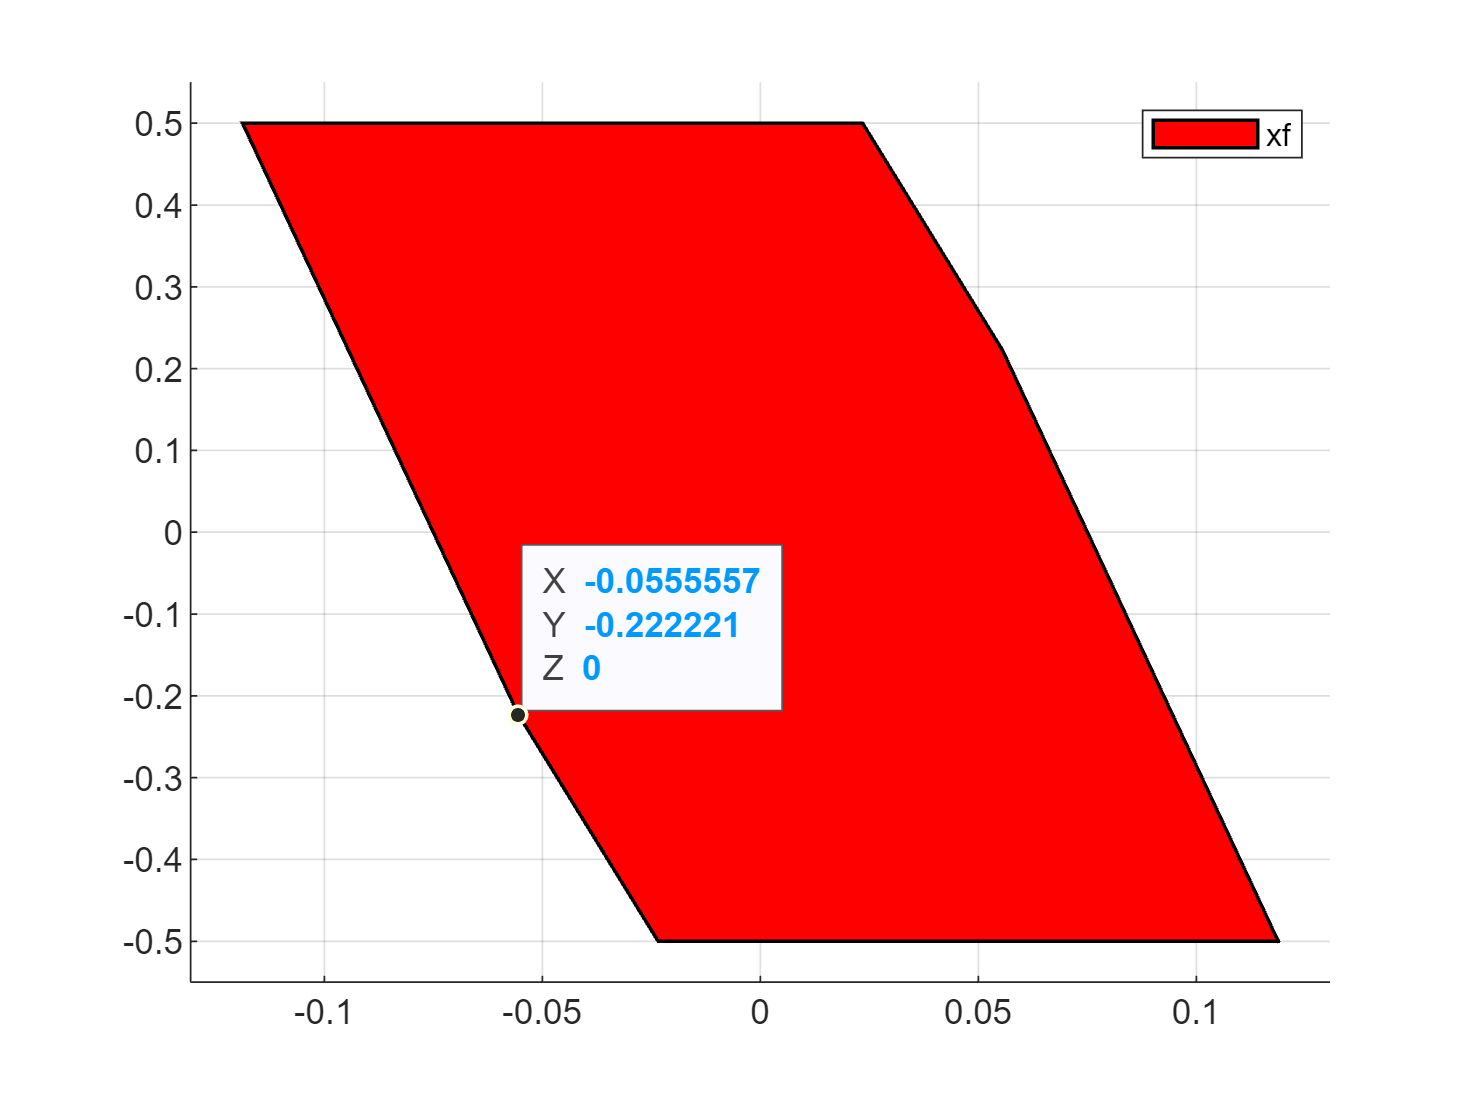

model.x.terminalSet = Tset;
figure()
plot(Tset)
legend("xf")

XN = Tset;
N=2

N = 2

for i = 1:N
    pre_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = pre_XN.intersect(X);
end
X0=XN

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  14 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


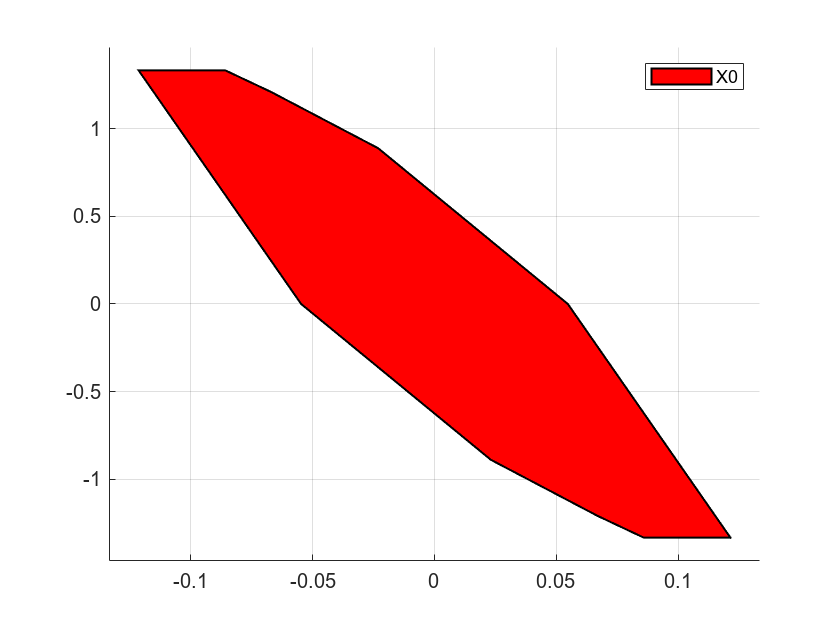

figure()
plot(X0)
legend("X0")
hold off

%p1
x0 = [-0.1;1.3];
Nsim = 10;


model.x.with('terminalPenalty');
model.x.terminalPenalty = QuadFunction(pf1);
mpc  = MPCController(model, 2);
loop = ClosedLoop(mpc, model);
datap1  = loop.simulate(x0, Nsim);

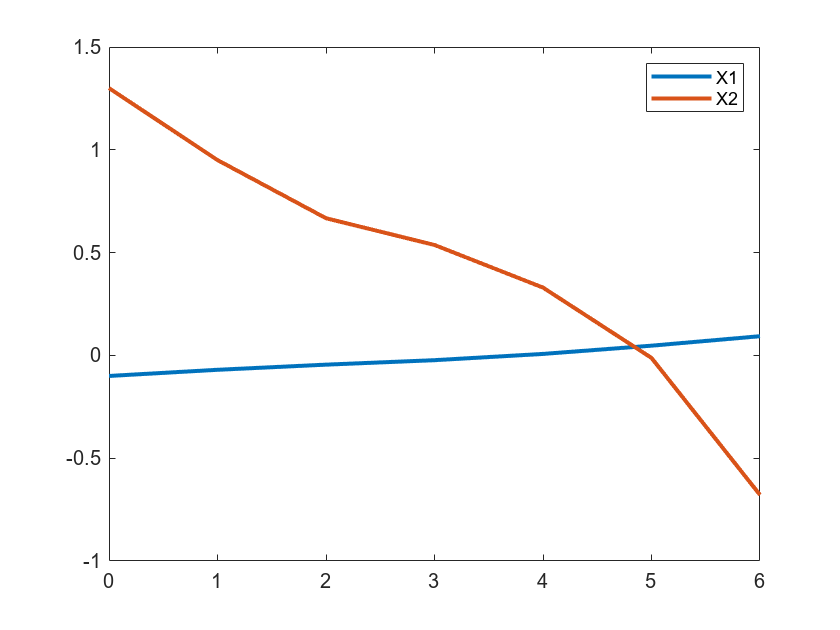


figure()

plot(0:6,datap1.X(1,:),'LineWidth',2)
hold on
plot(0:6,datap1.X(2,:),'LineWidth',2)
legend('X1','X2')
hold off

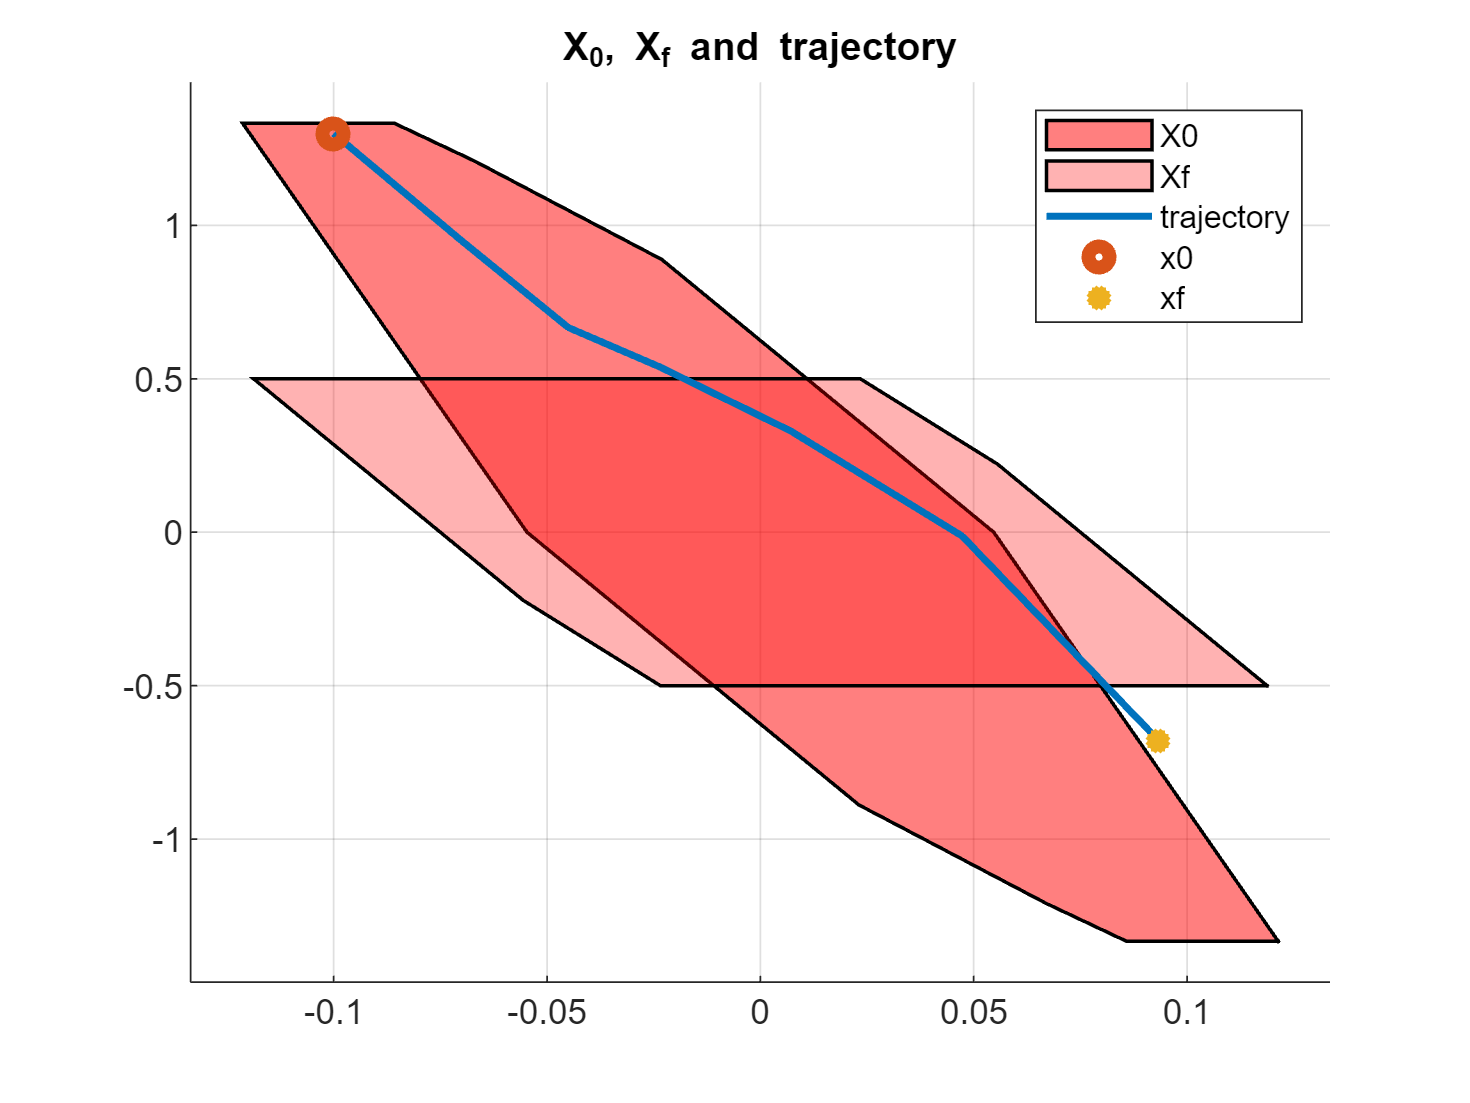

figure()
plot(X0,'alpha',0.5,Tset,'alpha',0.3)
hold on
plot(datap1.X(1,:),datap1.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o','LineWidth',4)
scatter(datap1.X(1,end), datap1.X(2,end), '*','LineWidth',4)
title('X_0, X_f and trajectory')
legend('X0','Xf','trajectory','x0','xf')

%p2
x0 = [-0.1;1.3];
Nsim = 20;
model.x.with('terminalPenalty');

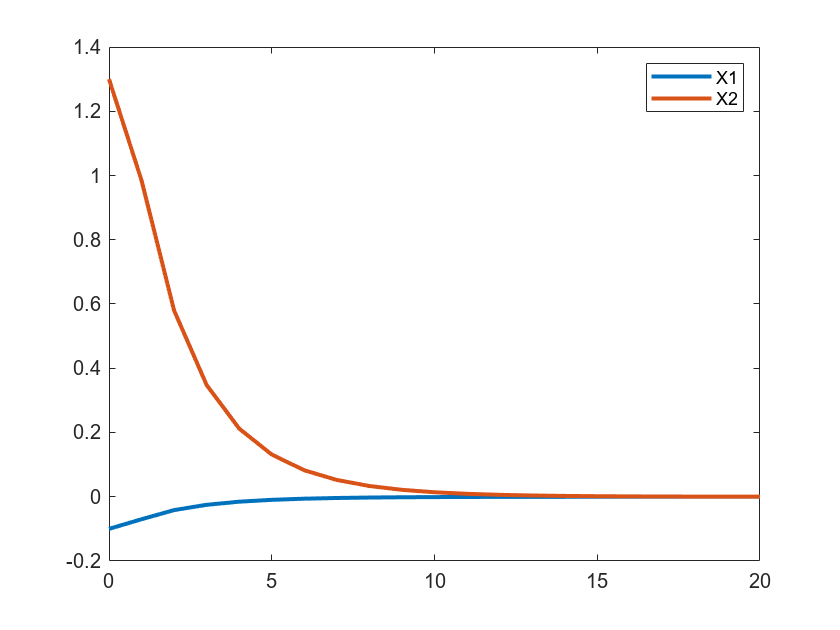

model.x.terminalPenalty = QuadFunction(pf2);
mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, Nsim);

figure()

plot(0:Nsim,data.X(1,:),'LineWidth',2)
hold on
plot(0:Nsim,data.X(2,:),'LineWidth',2)
legend('X1','X2')
hold off

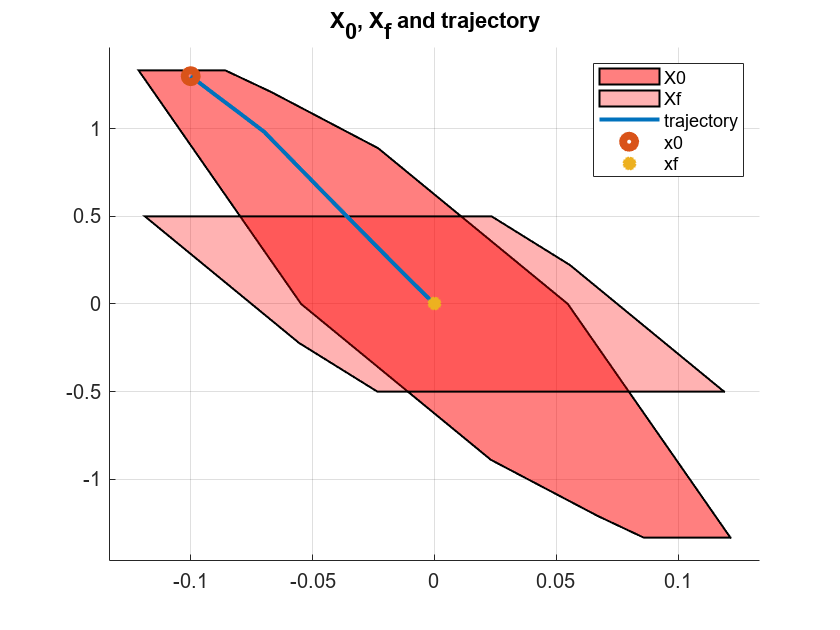

figure()
plot(X0,'alpha',0.5,Tset ,'alpha',0.3)
hold on
plot(data.X(1,:),data.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o','LineWidth',4)
scatter(data.X(1,end), data.X(2,end), '*','LineWidth',4)
title('X_0, X_f and trajectory')
legend('X0','Xf','trajectory','x0','xf')

% plot(data.X(2,end),'LineWidth',2)
% plot(X0,'alpha',0.5)
% hold on
% plot(Tset,'alpha',0.4)
% hold on

function [K_dp,P0,eigvalue_dp,N] = dp_func(A2,B2,N_input,Q,R,Pf)
Pkk = Pf;
for N=1:N_input
    count1=0;
    K_dp= -inv(R+B2'*Pkk*B2)*B2'*Pkk*A2;
    Pk  = Q + A2'*Pkk*A2 - A2'*Pkk*B2*inv(R+B2'*Pkk*B2)*B2'*Pkk*A2;
    Pkk = Pk;
    P0 = Pk;
    eigvalue_dp=eig(A2+B2*K_dp);
    for i =1:size(A2,1)
        if eigvalue_dp(i)^2<1
            count1=count1+1;
        end 
    end
    if count1==size(A2,1)
        fprintf("This is the result of dp solution\n")
        fprintf("the stable value of dp is %d",N);
        break
    end
end
end
function [k,Omega,Gamma,Q_bar,R_bar] = MPC_batch(A2,B2,N_input,Q,R,Pf)
for N=1:N_input
    n=size(A2,1);%A is nxn, get n
    p=size(B2,2);%B is nxp, get p
    Q_bar = blkdiag(kron(eye(N-1),Q),Pf);
    R_bar = kron(eye(N),R);
    Gamma = zeros(n*N,p*N);
    Omega = zeros(n*N,n);    
    for i=0:N-1
        Gamma = Gamma + kron(diag(ones(N-i,1),-i),A2^i*B2);
        Omega = Omega + [zeros(i*n,n); A2^(i+1); zeros((N-1-i)*n,n)];
    end
    kb=-inv(Gamma'*Q_bar*Gamma+R_bar)*Gamma'*Q_bar*Omega;
    k=kb(1,:);
end
end